% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de representación
Nx = 2048;
Ny = 2048;

% Condiciones de Muestreo
dx =6.513*mm;
dy =6.513*mm;

lambda = 633*nm;
k=(2*pi)/lambda

k = 9.9260e+06


distPropagacion=73*mm

distPropagacion = 0.0730

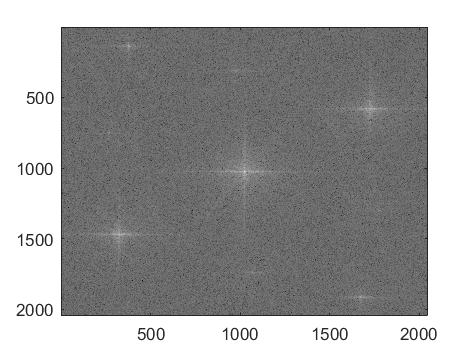

%Leer la imagen del holograma
ImHolo=imread("Hologram.tiff"); %Pixeles de 2048*2048
colormap("gray");



%Sacar transformada de Fourier del holograma
FourierTransform=fft2(ImHolo);
FFTHOLO = (fftshift(fft2(ImHolo)));
Transformada=imagesc(log(abs(fftshift(FourierTransform))));


% Se sacan los máximos
[maximosY,maximosX] = find(abs(FFTHOLO) == max(abs(FFTHOLO),[],"all"))

maximosY = 1025

maximosX = 1025

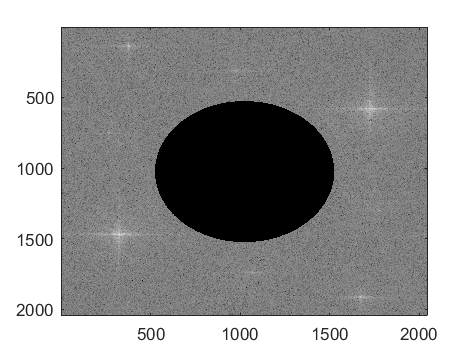


%Como el máximo central es el de mayor intensidad se elimina con un filtro
%para buscar los otros dos máximos

FFTHoloSinCentro = FFTHOLO.*(~filtroCircular([1025 1025],500,size(FFTHOLO)));
imagesc(log10(abs(FFTHoloSinCentro)))


%Deben encontrarse los dos máximos que dan cuenta de la información del
%objeto y onda de referencia

[maximosY1,maximosX1] = find(abs(FFTHoloSinCentro) == max(abs(FFTHoloSinCentro),[],"all"))

maximosY1 =         1469
         581


maximosX1 =          324
        1726


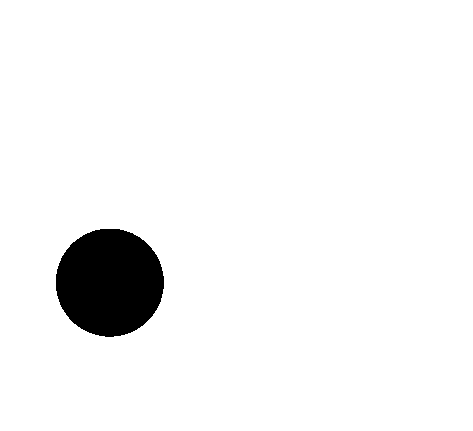


%Creación de la máscara para la selección de un orden

Mascara= (~filtroCircular([324 1469],300,size(FFTHOLO)));
imshow(Mascara);

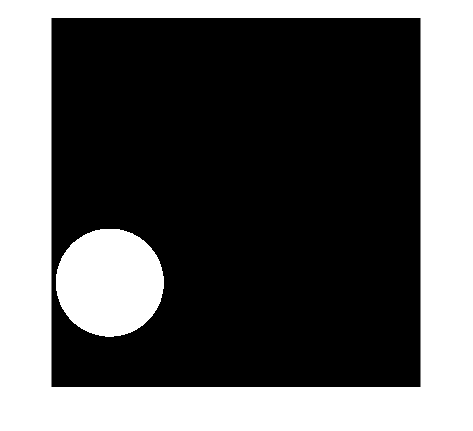

Filtro = imcomplement(Mascara); 
imshow(Filtro)

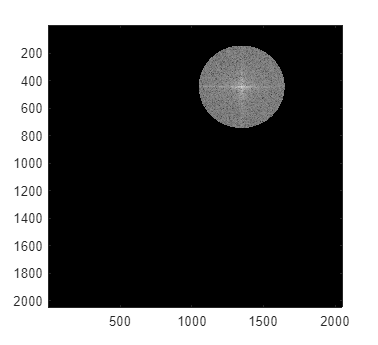

ImagenPropagar =   Image with properties:

           CData: [2048×2048 double]
    CDataMapping: 'scaled'

  Show all properties



%Se multiplica la transformada por la máscara para obtener un solo orden
OrdenMas=FFTHOLO.*Filtro;
ImagenPropagar=imagesc(log(abs(fftshift(OrdenMas.^2))))



%Se multiplica la onda de referencia con el holograma filtrado
%Transmitancia centrada
A=OndaPlana(lambda,angleDegrees,xRange,yRange);

%Para hallar la fase, se resta la coordenada del orden mas uno y se resta
%la de el centro y se encuentra el ángulo usando tangente

angleDegrees=(lambda/dx)

angleDegrees = 9.7190e-05

xRange=2048;
yRange=xRange;

A=OndaPlana(lambda,angleDegrees, xRange, yRange)

A = 	1.0e+-4 *

   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i   0.3780 - 0.8954i
   0.3780 - 0.8954i   0.3780 - 0.

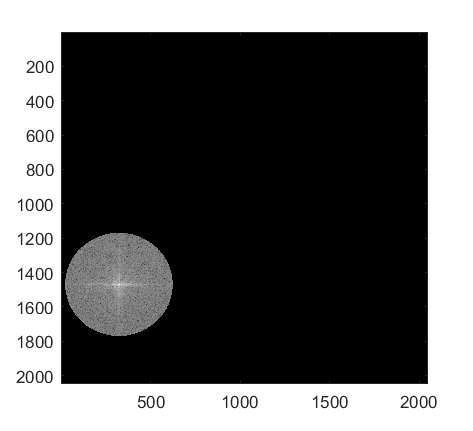

ImagenaPropagar =   Image with properties:

           CData: [2048×2048 double]
    CDataMapping: 'scaled'

  Show all properties


Multiplicacion=OrdenMas.*A;
ImagenaPropagar=imagesc(log(abs(Multiplicacion.^2)))